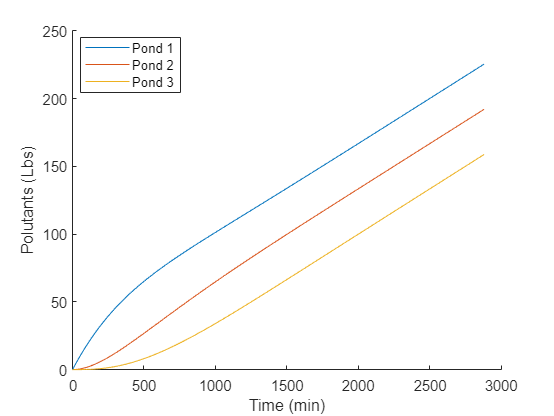

% system of differential equations (Order 1) to apply towards the Pond Pollution problem
% y would be = [x1(t), x2(t), x3(t)] where first row is x1, 2nd is x2, 3rd
% is x3
f = @(x,y) [...   
            0.002*y(3) - 0.002*y(1) + 0.2;
            0.002*y(1) - 0.002*y(2);
            0.002*y(2) - 0.002*y(3)];

% starting polution at each pond (alpha)
alp = [0.125,0.125,0.125];
a = 0; % time starts at x = 0
b = 2880; % time ends at 2880 minutes
N = 1000; % steps 

[t, w] = rung_kutta_systems(f, a, b, N, alp);
% plotting figure
figure;
xlabel("Time (min)");
ylabel("Polutants (Lbs)");
hold on;

plot(t,w(1,:));
plot(t,w(2,:));
plot(t,w(3,:));
%title("Pollution at Each Pond Over Time");
hold off;
legend("Pond 1", "Pond 2", "Pond 3");
legend('Position',[0.14586,0.77746,0.17857,0.13228])

pond_1 = [];
pond_2 = [];
pond_3 = [];
time_value = [];
count = 1;

% get appropiate values to get a rough idea of how the amount of pollution
% is increasing
disp(w(1, 400))

  111.0580



for i = 1 : 100 : N 
    
    pond_1(count) = w(1, i);
    pond_2(count) = w(2, i);
    pond_3(count) = w(3, i);
    time_value(count) = t(i);
    count = count + 1;
end

time_value = time_value';
pond_1 = pond_1';
pond_2 = pond_2';
pond_3 = pond_3';

% get table and display it
T = table(time_value, pond_1, pond_2, pond_3)

T = 10×4 table
    time_value    pond_1    pond_2    pond_3
    __________    ______    ______    ______

          0        0.125     0.125     0.125
        288       44.202    11.564    2.2092
        576        71.52     32.78    11.275
        864        92.31    54.851    26.014
       1152       111.24    75.818    43.712
       1440       129.97    95.816    62.592
       1728       148.86    115.29    81.823
       2016       167.92    134.56     101.1
       2304       187.07    153.75    120.36
       2592       206.25    172.94    139.58



disp(T);

    time_value    pond_1    pond_2    pond_3
    __________    ______    ______    ______

          0        0.125     0.125     0.125
        288       44.202    11.564    2.2092
        576        71.52     32.78    11.275
        864        92.31    54.851    26.014
       1152       111.24    75.818    43.712
       1440       129.97    95.816    62.592
       1728       148.86    115.29    81.823
       2016       167.92    134.56     101.1
       2304       187.07    153.75    120.36
       2592       206.25    172.94    139.58

